# GraFT Demo with NWB

## Introduction

In this tutorial, we will show how to use [GraFT](https://github.com/adamshch/GraFT-analysis) with an optical physiology experiment with standard two-photon imaging data, using [NWB](https://github.com/NeurodataWithoutBorders/matnwb) data format.  GraFT is a data-driven method for learning the fluorescence activity traces underlying a given calcium imaging video.  GraFT embeds the pixel-wise time traces in similarity-based graph which reflects the underlying structure of the data.  This makes using correlations between time-traces easier when isolating canonical time-traces in a filtered dictionary learning setting. 

## Installing MatNWB

Ensure that MatNWB is installed with its updated schema.  Use the code below within the brackets to install MatNWB from source. MatNWB works by automatically creating API classes based on the schema. Use [`generateCore`](https://neurodatawithoutborders.github.io/matnwb/doc/generateCore.html) to generate these classes.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd matnwb
addpath(genpath(pwd));
generateCore();
%}

## Set Up Paths & misc startups

For faster computation, GraFT takes advantage of the [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html), which lets you solve computationally and data-intensive problems using multicore processors, GPUs, and computer clusters.  The toolbox lets you use the full processing power of multicore desktops by executing applications on workers (MATLAB computational engines) that run locally on your system. Apart from adding all of the files in the repository to your current path, this is not a required step but it is recommended.

mydir = pwd;                                                               % assuming running from tutorial folder
addpath(genpath(mydir(1:idx(end)-1)));                                     % Add all the files in the repo
ncores       = feature('numcores');                                        % Sets number of cores
core_percent = 1;                                                          % Sets the percent of cores to use
if isempty(gcp('nocreate'))
    parpool(ceil(core_percent*ncores),'IdleTimeout',5000);                 % If no parpool, make one
end
warning(sprintf('Using %d cores for parpool. Change var core_percent above if necessary',ceil(core_percent*ncores)));

RandStream.setGlobalStream(RandStream('mt19937ar'));                       % Set the random stream

## Reading NWB File

To create the sample NWB file used in this tutorial, please see nwb_ophys_tutorial.mlx.

nwb = nwbRead('ophys_graft_tutorial.nwb', 'ignorecache')

nwb =   NwbFile with properties:

                                             nwb_version: '2.5.0'
                                        file_create_date: [1×1 types.untyped.DataStub]
                         general_source_script_file_name: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: 2018-04-25T02:30:03.000000-07:00
                               timestamps_reference_time: 2018-04-25T02:30:03.000000-07:00
                                             acquisition: [1×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data.  We want to use the raw physiology data, which will be in acquisition under 'TwoPhotonSeires' DataStub. 

nwb.acquisition.get('TwoPhotonSeries').data

ans =   DataStub with properties:

    filename: 'ophys_graft_tutorial.nwb'
        path: '/acquisition/TwoPhotonSeries/data'
        dims: [512 512 8000]
       ndims: 3
    dataType: 'double'


This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Access the data in the matrix using the `load` method. 

`load` with no input arguments reads the entire dataset:

% nwb.acquisition.get('TwoPhotonSeries').data.load;

## Data Selection

If all you need is a section of the data, you can read only that section by indexing the `DataStub` object like a normal array in MATLAB.  This will just read the selected region from disk into RAM. This technique is particularly useful if you are dealing with a large dataset that is too big to fit entirely into your available RAM. 

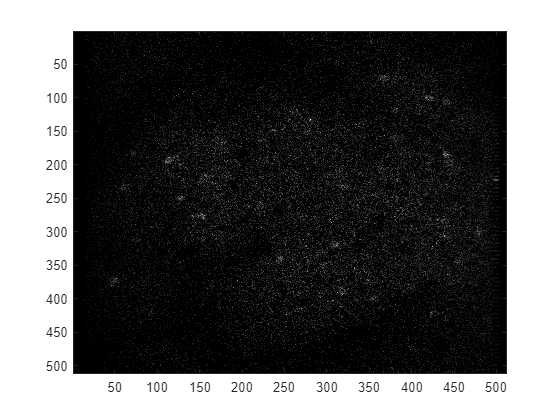

sample = nwb.acquisition.get('TwoPhotonSeries').data(:,:,1);          
imagesc(sample); colormap gray

For this tutorial, only half of the data will be used for demonstration purposes with a smaller field of view

N    = 1:4000;                                                                  % depth
Xsel = 151:350;                                                                 % 200x200 FOV                                    
Ysel = 151:350;
if isempty(N);       N = 1:nwb.acquisition.get('TwoPhotonSeries').data.dims(3);end
if isempty(Xsel); Xsel = 1:nwb.acquisition.get('TwoPhotonSeries').data.dims(1);end
if isempty(Ysel); Ysel = 1:nwb.acquisition.get('TwoPhotonSeries').data.dims(2);end

data = [];                                                                      % initializing data structure
data.nam    = 'neurofinder.02.00';                                              % name
data.Fsim   = nwb.acquisition.get('TwoPhotonSeries').data(Xsel,Ysel,N);         % loading data

## Motion Correction (Optional)

This step may be required if not already run...

params.motion_correct = false;                                              % default -> false
if params.motion_correct                                                    % use normcorre
    try
        options_rigid = NoRMCorreSetParms('d1',size(data.Fsim,1),'d2',size(data.Fsim,2), ...
            'bin_width',50,'max_shift',10,'us_fac',2,'iter',5,'init_batch',200);
        [data.Fsim,shifts,template,options,col_shift] = normcorre(data.Fsim,options_rigid);
    catch me
        error('motion correction: normcorre not found. Download from https://github.com/flatironinstitute/NoRMCorre and add to path')
    end
end
data.Fsim = data.Fsim/median(data.Fsim(:));                                 % update data

If you so choose, you can always save back analysis back into NWB format. In this case, to save motion corrected data, we can add a [`MotionCorrection`](https://pynwb.readthedocs.io/en/stable/pynwb.ophys.html#pynwb.ophys.MotionCorrection) object, which is a [`MultiContainerInterface`](https://pynwb.readthedocs.io/en/stable/pynwb.core.html#pynwb.core.MultiContainerInterface) (similar to [`Position`](https://pynwb.readthedocs.io/en/stable/pynwb.behavior.html#pynwb.behavior.Position)) which holds 1 or more [`CorrectedImageStack`](https://pynwb.readthedocs.io/en/stable/pynwb.ophys.html#pynwb.ophys.CorrectedImageStack) objects.

% assign data to appropriate module
corrected = types.core.ImageSeries( ...
    'description', 'Motion corrected data', ...
    'data', data.Fsim, ...
    'data_unit', 'n.a.', ...
    'starting_time_rate', 1.0, ...
    'starting_time', 0.0);

% create processing module for storing processed motion corrected data in
% the NWB File, then add the ImageSeries to the processing module
corrected_ophys_module = types.core.ProcessingModule( ...
    'description', 'holds motion corrected ophys data');

corrected_ophys_module.nwbdatainterface.set('motion_corrected', corrected);
nwb.processing.set('motioncorrect', corrected_ophys_module);

% export if desired
% nwbExport(nwb, 'motioncorrected.nwb')               % save the NWB file

## Data Denoising (Optional)

Here, we do simple time-trace wavelet denoising and update the data

data.Fsim = denoiseCIinTime(data.Fsim);

Smoothing...starting denoising
reshaping
done.


## Basic GraFT Parameters

These parameters can change frequently using data with varying size (GBs) and field of view. 

saveDir  = '.';                                                             % Set the path where the output should be saved to
usePatch = true;                                                            % Select if patchGraFT or regular GraFT should be used. For bigger field-of-views (>150 pix X 150 pix), patchGraFT is recommended
params.lambda    = 0.05;                                                    % Sparsity parameter
params.lamForb   = 0.2;                                                     % parameter to control how much to weigh extra time-traces
params.lamCorr   = 0.1;                                                     % Parameter to prevent overly correlated dictionary elements
params.n_dict    = 4;                                                       % Choose how many components (per patch) will be initialized. Note: the final number of coefficients may be less than this due to lack of data variance and merging of components.
params.patchSize = 50;                                                      % Choose the size of the patches to break up the image into (squares with patchSize pixels on each side)

#### Advanced Parameters

A full set of parameters and defaults is specified in the bottom of the GraFT main function (subfunction checkAllParameters()).

params.lamCont          = 0.1;                                              % parameter to control how much to weigh the previous estimate (continuity term)
params.grad_type        = 'full_ls_cor';                                    % type of dictionary update
params.lamContStp       = 0.9;                                              % Decay rate of the continuation parameter
params.plot             = true;                                             % Set whether to plot intermediary variables
params.create_memmap    = false;                                            %
params.verbose          = 0;                                                % Level of verbose output
params.normalizeSpatial = true;
corr_kern.w_time        = 0;                                                % Initialize the correlation kernel struct
corr_kern.reduce_dim    = true;
corr_kern.corrType      = 'embedding';                                      % Set the correlation type to "graph embedding"

## Running GraFT

This is how to run the main function:

fprintf('Running with parameters lambda = %f, lamforb = %f, lamcont = %f, lamCorr = %f.\n', ...
    params.lambda, params.lamForb, params.lamCont, params.lamCorr);

Running with parameters lambda = 0.050000, lamforb = 0.200000, lamcont = 0.100000, lamCorr = 0.100000.


if usePatch
    [S, D] = patchGraFT(data.Fsim,params.n_dict,[],corr_kern,params);       % Learn the dictionary using patch-based code
else
    [D, S] = GraFT(data.Fsim, [], corr_kern, params);                       % Learn the dictionary (no patching - will be much more memory intensive and slower)
end

Patch construct not provided; constructing patches...done.
Running GraFT on patch # 1 out of 25.
Finished processing patch # 1 out of 25 (Num D = 4) in 36.543367 s.
Running GraFT on patch # 2 out of 25.
Finished processing patch # 2 out of 25 (Num D = 4) in 20.165421 s.
Running GraFT on patch # 3 out of 25.
Finished processing patch # 3 out of 25 (Num D = 4) in 31.897171 s.
Running GraFT on patch # 4 out of 25.
Finished processing patch # 4 out of 25 (Num D = 4) in 12.326529 s.
Running GraFT on patch # 5 out of 25.
Finished processing patch # 5 out of 25 (Num D = 4) in 20.632430 s.
Running GraFT on patch # 6 out of 25.
Finished processing patch # 6 out of 25 (Num D = 4) in 22.439450 s.
Running GraFT on patch # 7 out of 25.
Finished processing patch # 7 out of 25 (Num D = 4) in 18.264845 s.
Running GraFT on patch # 8 out of 25.
Finished processing patch # 8 out of 25 (Num D = 4) in 40.994047 s.
Running GraFT on patch # 9 out of 25.
Finished processing patch # 9 out of 25 (Num D = 4) in 

fprintf('Finished running GraFT.\n')

Finished running GraFT.


The commented line is how to call GraFT if you don't want to run the above lines independently

% corr_kern = checkCorrKern(data_obj, corr_kern, params.verbose); 

## Plotting Results

Here, the MATLAB [MovieSlider Toolbox](https://github.com/sakoay/MovieSlider) is used to create an embeddable panel for playback, scrolling, and contrast/color map adjustment of our results. 

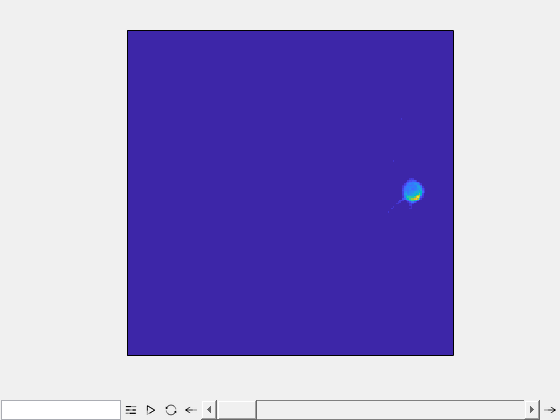

Sthresh = S;
for ll = 1:size(Sthresh,3)
    Sthresh(:,:,ll) = Sthresh(:,:,ll).*(Sthresh(:,:,ll) > 0.05*max(max(Sthresh(:,:,ll),[],1), [], 2));
end
clear ll
MovieSlider(Sthresh);

## Saving Results

This method covers how to save results as a .mat file using the location from 'saveDir' under Basic GraFT Parameters. 

if params.normalizeSpatial
    normType = 'spatial';
else
    normType = 'temporal';
end
saveName = sprintf('nfRun_%d_%d_%d_%d_%s', ...
    round(100*params.lambda), round(100*params.lamForb),...
    round(100*params.lamCorr), round(100*params.lamCont),...
    normType); % Set the save name to store results in
fprintf('Saving results to %s...\n', saveName)

Saving results to nfRun_5_20_10_10_spatial...


% save(fullfile(saveDir,[saveName, '.mat']),'S','D','params','-v7.3')  % Save the results

Of course, one can also save it into processing modules of a NWB data file. In this case, I am creating a new NWB named 'GraFT_Analysis.nwb' containing processed motion corrected data, as well as spatial and temporal data from GraFT toolbox.

% assign data timeseries
D_timeseries = types.core.TimeSeries( ...
    'description', 'GraFT Temporal TimeSeries', ...
    'data', D, ...
    'data_unit', 'n.a.', ...
    'starting_time_rate', 1.0, ...
    'starting_time', 0.0);
D_timeseries_module = types.core.ProcessingModule( ...
    'description', 'holds GraFT timeseries data');
D_timeseries_module.nwbdatainterface.set('D', D_timeseries);

% assign spatial data
S_data = types.core.ImageSeries( ...
    'description', 'GraFT Spatial Image Files', ...
    'data', S, ...
    'data_unit', 'n.a.', ...
    'starting_time_rate', 1.0, ...
    'starting_time', 0.0);
S_spatial_module = types.core.ProcessingModule( ...
    'description', 'holds GraFT timeseries data');
S_spatial_module.nwbdatainterface.set('S', S_data);

% adding to NWB
nwb.processing.set('GraFT_D', D_timeseries_module);
nwb.processing.set('GraFT_S', S_spatial_module);

% write the file and export
% nwbExport(nwb, 'GraFT_Analysis.nwb');

# Learn more about GraFT!

### Visit the [GitHub](https://github.com/adamshch/GraFT-analysis) page to learn about other functions and please reach out if you want to see other use cases!